# 62743 DSP — Week 11 Tuesday

% FIR Design via Fourier Transform (Fourier-series method)
% Exercises 1 & 2 from "Uge 11 – Tirsdag"

clear; close all; clc;

imgDir = 'C:\Users\Mads2\DTU\Obsidian\Courses\DSP\Images';
if ~exist(imgDir, 'dir')
    mkdir(imgDir);
end


% Common setup
Fs  = 8000;              % Sampling frequency [Hz]
Nfft = 2048;             % FFT grid for freqz

## Exercise 1 — FIR Low-pass via Fourier Transform

% 1-A) Cutoff and ideal LP impulse response (infinite-length)
Fc = 800;                           % Cutoff [Hz]
wc = 2*pi*Fc/Fs;                    % Digital cutoff (rad/sample)

fprintf('Exercise 1-A:\n');

Exercise 1-A:


fprintf('  omega_c = %.6f rad/sample = %.3f*pi\n\n', wc, wc/pi);

  omega_c = 0.628319 rad/sample = 0.200*pi




% Ideal low-pass impulse response (infinite-length)
% h_LP_ideal[n] = sin(wc*n)/(pi*n), n ~= 0
% h_LP_ideal[0] = wc/pi
hLP_ideal = @(n) (n == 0).*(wc/pi) + ...
                 (n ~= 0).* (sin(wc*n)./(pi*n));

% Example: show a few ideal samples around n=0
n_test = -5:5;
h_test = hLP_ideal(n_test);
disp('Ideal low-pass samples h_LP_ideal[n] for n = -5:5:');

Ideal low-pass samples h_LP_ideal[n] for n = -5:5:


disp(table(n_test(:), h_test(:), 'VariableNames',{'n','hLP_ideal'}));

    n     hLP_ideal 
    __    __________

    -5    7.7963e-18
    -4      0.046774
    -3       0.10091
    -2       0.15137
    -1        0.1871
     0           NaN
     1        0.1871
     2       0.15137
     3       0.10091
     4      0.046774
     5    7.7963e-18



fprintf('\nIdeal LP response is infinite length -> not directly implementable.\n\n');


Ideal LP response is infinite length -> not directly implementable.



## 1-B) 7-tap LP FIR coefficients

Ntaps1 = 7;
M1     = Ntaps1 - 1;         % Filter order
K1     = (Ntaps1 - 1)/2;     % Symmetry index (must be integer for odd Ntaps)

fprintf('Exercise 1-B:\n');

Exercise 1-B:


fprintf('  Ntaps = %d, M = %d, K = %d\n', Ntaps1, M1, K1);

  Ntaps = 7, M = 6, K = 3



% Truncate ideal h[n] to n = -K1:K1
n_trunc1   = -K1:K1;
hLP_trunc1 = hLP_ideal(n_trunc1);     % symmetric, non-causal view

% For implementation we simply store the symmetric coeffs as b[n]
B_LP7 = hLP_trunc1;                   % length 7, indices 0..6

fprintf('  7-tap LP coefficients (B_LP7):\n    ');

  7-tap LP coefficients (B_LP7):
    

fprintf('%.6f ', B_LP7);

0.100910 0.151365 0.187098 NaN 0.187098 0.151365 0.100910 

fprintf('\n\n');


## 1-C) Transfer function H(z) for 7-tap LP

A_LP7 = 1;    % FIR => denominator is 1

% (Optionally, with Symbolic Toolbox you could do:)
% syms z
% H7_sym = poly2sym(fliplr(B_LP7), z^-1);


## 1-D) Magnitude and phase response for 7-tap LP

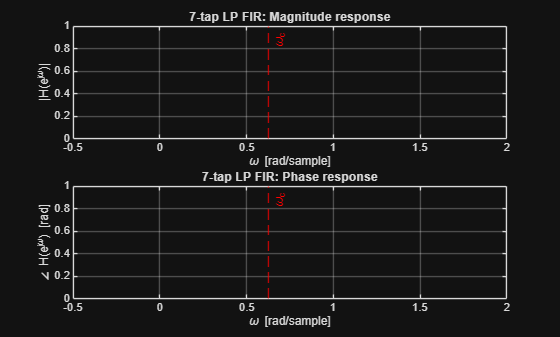

[H7, w7] = freqz(B_LP7, A_LP7, Nfft);

figure;
subplot(2,1,1);
plot(w7, abs(H7), 'LineWidth', 1.5); grid on; hold on;
xline(wc, '--r', '\omega_c');
xlabel('\omega [rad/sample]');
ylabel('|H(e^{j\omega})|');
title('7-tap LP FIR: Magnitude response');

subplot(2,1,2);
plot(w7, unwrap(angle(H7)), 'LineWidth', 1.5); grid on; hold on;
xline(wc, '--r', '\omega_c');
xlabel('\omega [rad/sample]');
ylabel('\angle H(e^{j\omega}) [rad]');
title('7-tap LP FIR: Phase response');

exportgraphics(gcf, fullfile(imgDir, 'DSP_U11_Tirsdag_1D_LP7_mag_phase.png'), 'Resolution', 300);

## 1-E) Impulse response plot (7 taps)

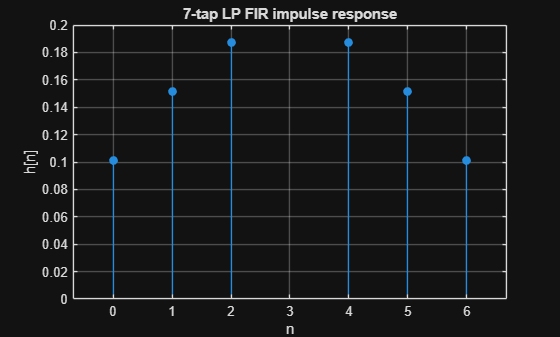

figure;
stem(0:M1, B_LP7, 'filled');
grid on;
xlabel('n');
ylabel('h[n]');
title('7-tap LP FIR impulse response');
exportgraphics(gcf, fullfile(imgDir, 'DSP_U11_Tirsdag_1E_LP7_impulse.png'), 'Resolution', 300);

## 1-F) 51-tap LP FIR with same cutoff

Ntaps51 = 51;
M51     = Ntaps51 - 1;
K51     = (Ntaps51 - 1)/2;

fprintf('Exercise 1-F:\n');

Exercise 1-F:


fprintf('  Ntaps = %d, M = %d, K = %d\n', Ntaps51, M51, K51);

  Ntaps = 51, M = 50, K = 25


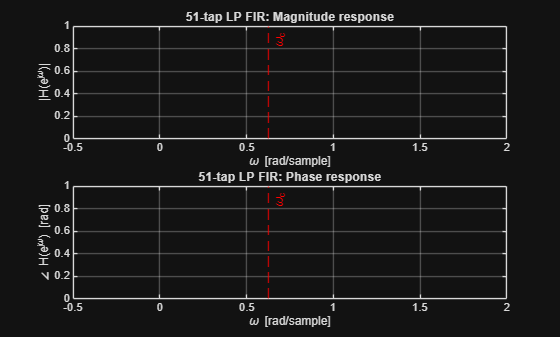


n_trunc51   = -K51:K51;
hLP_trunc51 = hLP_ideal(n_trunc51);
B_LP51      = hLP_trunc51;

[H51, w51] = freqz(B_LP51, 1, Nfft);

figure;
subplot(2,1,1);
plot(w51, abs(H51), 'LineWidth', 1.5); grid on; hold on;
xline(wc, '--r', '\omega_c');
xlabel('\omega [rad/sample]');
ylabel('|H(e^{j\omega})|');
title('51-tap LP FIR: Magnitude response');

subplot(2,1,2);
plot(w51, unwrap(angle(H51)), 'LineWidth', 1.5); grid on; hold on;
xline(wc, '--r', '\omega_c');
xlabel('\omega [rad/sample]');
ylabel('\angle H(e^{j\omega}) [rad]');
title('51-tap LP FIR: Phase response');
exportgraphics(gcf, fullfile(imgDir, 'DSP_U11_Tirsdag_1F_LP51_mag_phase.png'), 'Resolution', 300);

## 1-G) Comparison: 7 vs 51 taps

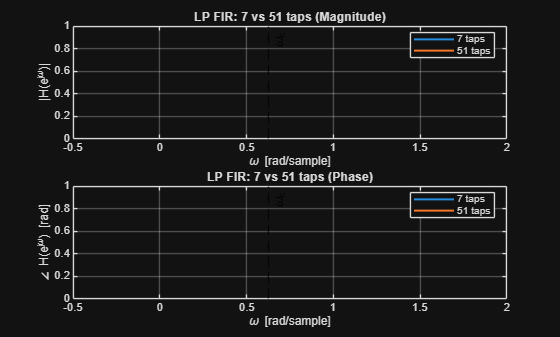

figure;
subplot(2,1,1);
plot(w7,  abs(H7),  'LineWidth', 1.5); hold on;
plot(w51, abs(H51), 'LineWidth', 1.5);
grid on; xline(wc, '--k', '\omega_c');
legend('7 taps','51 taps','Location','best');
xlabel('\omega [rad/sample]');
ylabel('|H(e^{j\omega})|');
title('LP FIR: 7 vs 51 taps (Magnitude)');

subplot(2,1,2);
plot(w7,  unwrap(angle(H7)),  'LineWidth', 1.5); hold on;
plot(w51, unwrap(angle(H51)), 'LineWidth', 1.5);
grid on; xline(wc, '--k', '\omega_c');
legend('7 taps','51 taps','Location','best');
xlabel('\omega [rad/sample]');
ylabel('\angle H(e^{j\omega}) [rad]');
title('LP FIR: 7 vs 51 taps (Phase)');

exportgraphics(gcf, fullfile(imgDir, 'DSP_U11_Tirsdag_1G_LP7vs51_mag_phase.png'), 'Resolution', 300);


fprintf('Exercise 1-G:\n');

Exercise 1-G:


fprintf('  - 51 taps => narrower transition band and lower stopband sidelobes.\n');

  - 51 taps => narrower transition band and lower stopband sidelobes.


fprintf('  - Symmetric FIR => approximately linear phase in passband (pure delay K samples).\n');

  - Symmetric FIR => approximately linear phase in passband (pure delay K samples).


fprintf('  - Stopband ripples correspond to Gibbs oscillations from rectangular truncation.\n\n');

  - Stopband ripples correspond to Gibbs oscillations from rectangular truncation.



## Exercise 2 — FIR Band-pass via Fourier Transform

% 2-A) Angular cutoffs, M, K, and ideal BP impulse response
Fs2 = 8000;
FL  = 2000;     % Lower cutoff [Hz]
FH  = 2400;     % Upper cutoff [Hz]

wL = 2*pi*FL/Fs2;        % 0.5*pi
wH = 2*pi*FH/Fs2;        % 0.6*pi

fprintf('Exercise 2-A:\n');

Exercise 2-A:


fprintf('  omega_L = %.6f rad/sample = %.3f*pi\n', wL, wL/pi);

  omega_L = 1.570796 rad/sample = 0.500*pi


fprintf('  omega_H = %.6f rad/sample = %.3f*pi\n\n', wH, wH/pi);

  omega_H = 1.884956 rad/sample = 0.600*pi




NtapsBP = 9;
M_BP    = NtapsBP - 1;
K_BP    = (NtapsBP - 1)/2;

fprintf('  Ntaps = %d, M = %d, K = %d\n\n', NtapsBP, M_BP, K_BP);

  Ntaps = 9, M = 8, K = 4




% Ideal band-pass impulse response (infinite-length)
% h_BP_ideal[n] = (sin(wH*n) - sin(wL*n)) / (pi*n), n ~= 0
% h_BP_ideal[0] = (wH - wL)/pi
hBP_ideal = @(n) (n == 0).*((wH - wL)/pi) + ...
                 (n ~= 0).*((sin(wH*n) - sin(wL*n))./(pi*n));

nBP_trunc = -K_BP:K_BP;
hBP_trunc = hBP_ideal(nBP_trunc);

disp('  Ideal BP samples h_BP_ideal[n] for n = -4:4:');

  Ideal BP samples h_BP_ideal[n] for n = -4:4:


disp(table(nBP_trunc(:), hBP_trunc(:), 'VariableNames',{'n','hBP_ideal'}));

    n     hBP_ideal
    __    _________

    -4     0.075683
    -3     0.043737
    -2    -0.093549
    -1    -0.015579
     0          NaN
     1    -0.015579
     2    -0.093549
     3     0.043737
     4     0.075683



fprintf('\nIdeal BP impulse response is infinite length before truncation (IIR-type),\n');


Ideal BP impulse response is infinite length before truncation (IIR-type),


fprintf('but becomes FIR after truncation to n = -K..K and shifting to 0..M.\n\n');

but becomes FIR after truncation to n = -K..K and shifting to 0..M.



## 2-B) 9-tap BP FIR coefficients

bBP9 = hBP_trunc;    % symmetric coefficients (length 9)

fprintf('Exercise 2-B:\n');

Exercise 2-B:


fprintf('  9-tap BP coefficients (bBP9):\n    ');

  9-tap BP coefficients (bBP9):
    

fprintf('%.6f ', bBP9);

0.075683 0.043737 -0.093549 -0.015579 NaN -0.015579 -0.093549 0.043737 0.075683 

fprintf('\n\n');


## 2-C) Magnitude and phase of 9-tap BP

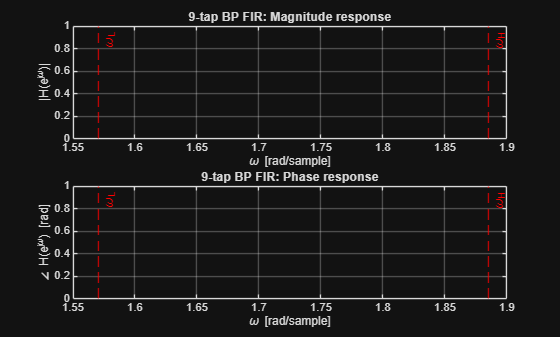

[HBP9, wBP9] = freqz(bBP9, 1, Nfft);

figure;
subplot(2,1,1);
plot(wBP9, abs(HBP9), 'LineWidth', 1.5); grid on; hold on;
xline(wL, '--r', '\omega_L');
xline(wH, '--r', '\omega_H');
xlabel('\omega [rad/sample]');
ylabel('|H(e^{j\omega})|');
title('9-tap BP FIR: Magnitude response');

subplot(2,1,2);
plot(wBP9, unwrap(angle(HBP9)), 'LineWidth', 1.5); grid on; hold on;
xline(wL, '--r', '\omega_L');
xline(wH, '--r', '\omega_H');
xlabel('\omega [rad/sample]');
ylabel('\angle H(e^{j\omega}) [rad]');
title('9-tap BP FIR: Phase response');
exportgraphics(gcf, fullfile(imgDir, 'DSP_U11_Tirsdag_2C_BP9_mag_phase.png'), 'Resolution', 300);

## 2-D) 101-tap BP FIR and comparison

NtapsBP101 = 101;
M_BP101    = NtapsBP101 - 1;
K_BP101    = (NtapsBP101 - 1)/2;

fprintf('Exercise 2-D:\n');

Exercise 2-D:


fprintf('  Ntaps = %d, M = %d, K = %d\n', NtapsBP101, M_BP101, K_BP101);

  Ntaps = 101, M = 100, K = 50


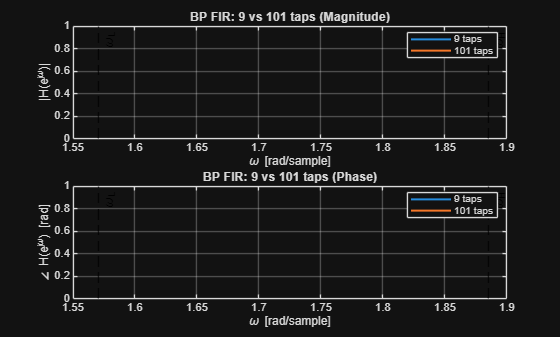


nBP_trunc101 = -K_BP101:K_BP101;
hBP_trunc101 = hBP_ideal(nBP_trunc101);
bBP101       = hBP_trunc101;

[HBP101, wBP101] = freqz(bBP101, 1, Nfft);

figure;
subplot(2,1,1);
plot(wBP9,   abs(HBP9),   'LineWidth', 1.5); hold on;
plot(wBP101, abs(HBP101), 'LineWidth', 1.5);
grid on;
xline(wL, '--k', '\omega_L');
xline(wH, '--k', '\omega_H');
legend('9 taps','101 taps','Location','best');
xlabel('\omega [rad/sample]');
ylabel('|H(e^{j\omega})|');
title('BP FIR: 9 vs 101 taps (Magnitude)');

subplot(2,1,2);
plot(wBP9,   unwrap(angle(HBP9)),   'LineWidth', 1.5); hold on;
plot(wBP101, unwrap(angle(HBP101)), 'LineWidth', 1.5);
grid on;
xline(wL, '--k', '\omega_L');
xline(wH, '--k', '\omega_H');
legend('9 taps','101 taps','Location','best');
xlabel('\omega [rad/sample]');
ylabel('\angle H(e^{j\omega}) [rad]');
title('BP FIR: 9 vs 101 taps (Phase)');
exportgraphics(gcf, fullfile(imgDir, 'DSP_U11_Tirsdag_2D_BP9vs101_mag_phase.png'), 'Resolution', 300);


fprintf(['  Increasing Ntaps to 101 sharpens the transitions around omega_L and omega_H\n' ...
         '  and reduces stopband ripples. Symmetry again yields approximately linear\n' ...
         '  phase in the passband (constant group delay).\n']);

  Increasing Ntaps to 101 sharpens the transitions around omega_L and omega_H
  and reduces stopband ripples. Symmetry again yields approximately linear
  phase in the passband (constant group delay).
